# Stock Data - Risk-Returns Profile

## 1.

Load data from `stockData_withReturns.mat`.

load stockData_withReturns.mat

## 2. 

Estimate the covariance matrix for all stock returns using the `cov` function.

cMat = cov(rets)

cMat =     0.0028    0.0007    0.0008    0.0007    0.0005    0.0006    0.0010    0.0007    0.0010    0.0012    0.0006    0.0005    0.0008   -0.0003    0.0010    0.0010    0.0011    0.0006    0.0010    0.0003    0.0006    0.0007    0.0010    0.0011    0.0011    0.0007    0.0009    0.0005    0.0004    0.0007    0.0008    0.0007   -0.0000    0.0004    0.0006    0.0006    0.0002    0.0004    0.0004    0.0004    0.0003    0.0005    0.0007    0.0001    0.0003    0.0005    0.0005    0.0004    0.0003    0.0007
    0.0007    0.0014    0.0007    0.0004    0.0004    0.0004    0.0007    0.0004    0.0007    0.0010    0.0004    0.0005    0.0005    0.0001    0.0007    0.0008    0.0007    0.0003    0.0008    0.0002    0.0004    0.0005    0.0006    0.0007    0.0007    0.0005    0.0007    0.0003    0.0003    0.0005    0.0006    0.0005    0.0000    0.0004    0.0004    0.0005    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0005    0.0001    0.0003    0.0005    0.0005    0.0003    0.0003  

## 3. 

Calculate the expected returns by finding the mean return for each stock.  Store the result in a variable `ExpReturns`.

ExpReturns = mean(rets)

ExpReturns =     0.0003   -0.0008   -0.0012    0.0020    0.0003   -0.0004    0.0003   -0.0012    0.0003   -0.0015    0.0001    0.0001    0.0002    0.0013   -0.0003   -0.0001   -0.0008   -0.0011   -0.0001   -0.0005   -0.0004    0.0002   -0.0009   -0.0006   -0.0003   -0.0014   -0.0002    0.0005   -0.0008    0.0003    0.0003   -0.0003    0.0002   -0.0005   -0.0002    0.0001   -0.0007    0.0000    0.0001    0.0001   -0.0002   -0.0001    0.0001    0.0002   -0.0012   -0.0004   -0.0007   -0.0008   -0.0007   -0.0008


## 4. 

Create a 122-by-1000 matrix of randomly-generated weights. Each column of the matrix represents a different portfolio (collection of assets/stocks), where each stock contributes to the 1000 portfolios by a different amount (the weighting). Normalize the matrix so that each column sums to one.

weights = rand(size(rets,2), 1000);
weights = weights./sum(weights); % Normalize.
% Check sum of weightings
sum(weights)

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


## 5. 

Calculate the risk and weighted return for every portfolio in the matrix using the following equations: `risk = w'*cMat*w`and` weightedRet= ExpReturns*w`. Here, `w` is a single column of the weightings matrix (one portfolio), and `cMat`is the covariance matrix.

risk = zeros(size(weights,1),1);
weightedRet = zeros(1,size(weights,1));
for k=1:1000
    w = weights(:,k);
    risk(k) = w'*cMat*w;
    weightedRet(k) = ExpReturns*w;   
end

## 6.

Create a scatter of the Return vs Risk values calculated in step 5.

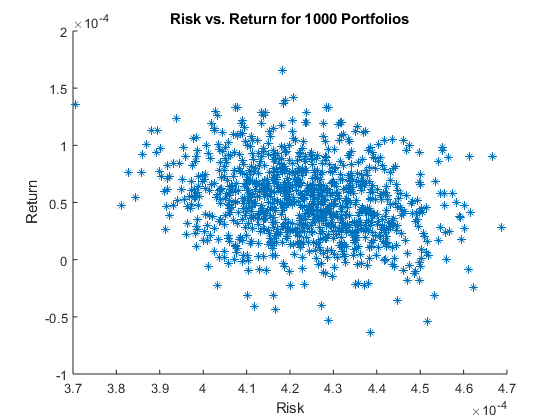

scatter(risk,weightedRet, '*');
title('Risk vs. Return for 1000 Portfolios')
xlabel('Risk')
ylabel('Return')